load data_neural_network.mat

[trainimages2 trainlabels2] = readMNIST('train-images.idx3-ubyte', 'train-labels.idx1-ubyte',60000 ,0);

[images2 labels2] = readMNIST('train-images.idx3-ubyte', 'train-labels.idx1-ubyte',10000 ,0);

trainimages = zeros(20,20,1,length(trainimages2));
for i = 1:length(trainimages)
    trainimages(:,:,:,i) = trainimages2(:,:,i);
end
images = zeros(20,20,1,length(images2));
for i = 1:length(images)
    images(:,:,:,i) = images2(:,:,i);
end
trainlabels = categorical(trainlabels2)

trainlabels = 60000×1 categorical array
     5 
     0 
     4 
     1 
     9 
     2 
     1 
     3 
     1 
     4 
     3 
     5 
     3 
     6 
     1 
     7 
     2 
     8 
     6 
     9 
     4 
     0 
     9 
     1 
     1 
     2 
     4 
     3 
     2 
     7 


labels = categorical(labels2)

labels = 10000×1 categorical array
     5 
     0 
     4 
     1 
     9 
     2 
     1 
     3 
     1 
     4 
     3 
     5 
     3 
     6 
     1 
     7 
     2 
     8 
     6 
     9 
     4 
     0 
     9 
     1 
     1 
     2 
     4 
     3 
     2 
     7 


# Network 1

layers = [
    imageInputLayer([20 20 1],"Name","imageinput")
    convolution2dLayer([3 8],32,"Name","conv_1","Padding","same")
    batchNormalizationLayer("Name","batchnorm_1")
    reluLayer("Name","relu_1")
    maxPooling2dLayer([2 2],"Name","maxpool_1","Padding","same","Stride",[2 2])
    convolution2dLayer([3 3],16,"Name","conv_2","Padding","same")
    batchNormalizationLayer("Name","batchnorm_2")
    reluLayer("Name","relu_2")
    maxPooling2dLayer([2 2],"Name","maxpool_2","Padding","same","Stride",[2 2])
    convolution2dLayer([3 3],32,"Name","conv_3","Padding","same")
    batchNormalizationLayer("Name","batchnorm_3")
    reluLayer("Name","relu_3")
    fullyConnectedLayer(10,"Name","fc")
    softmaxLayer("Name","softmax")
    classificationLayer("Name","classoutput")];

Training options

options = trainingOptions('sgdm', ...
    'InitialLearnRate',0.01, ...
    'MaxEpochs',4, ...
    'Shuffle','every-epoch', ...
    'ValidationFrequency',30, ...
    'Verbose',false, ...
    'Plots','training-progress');

Train Netowrk Using Training Data

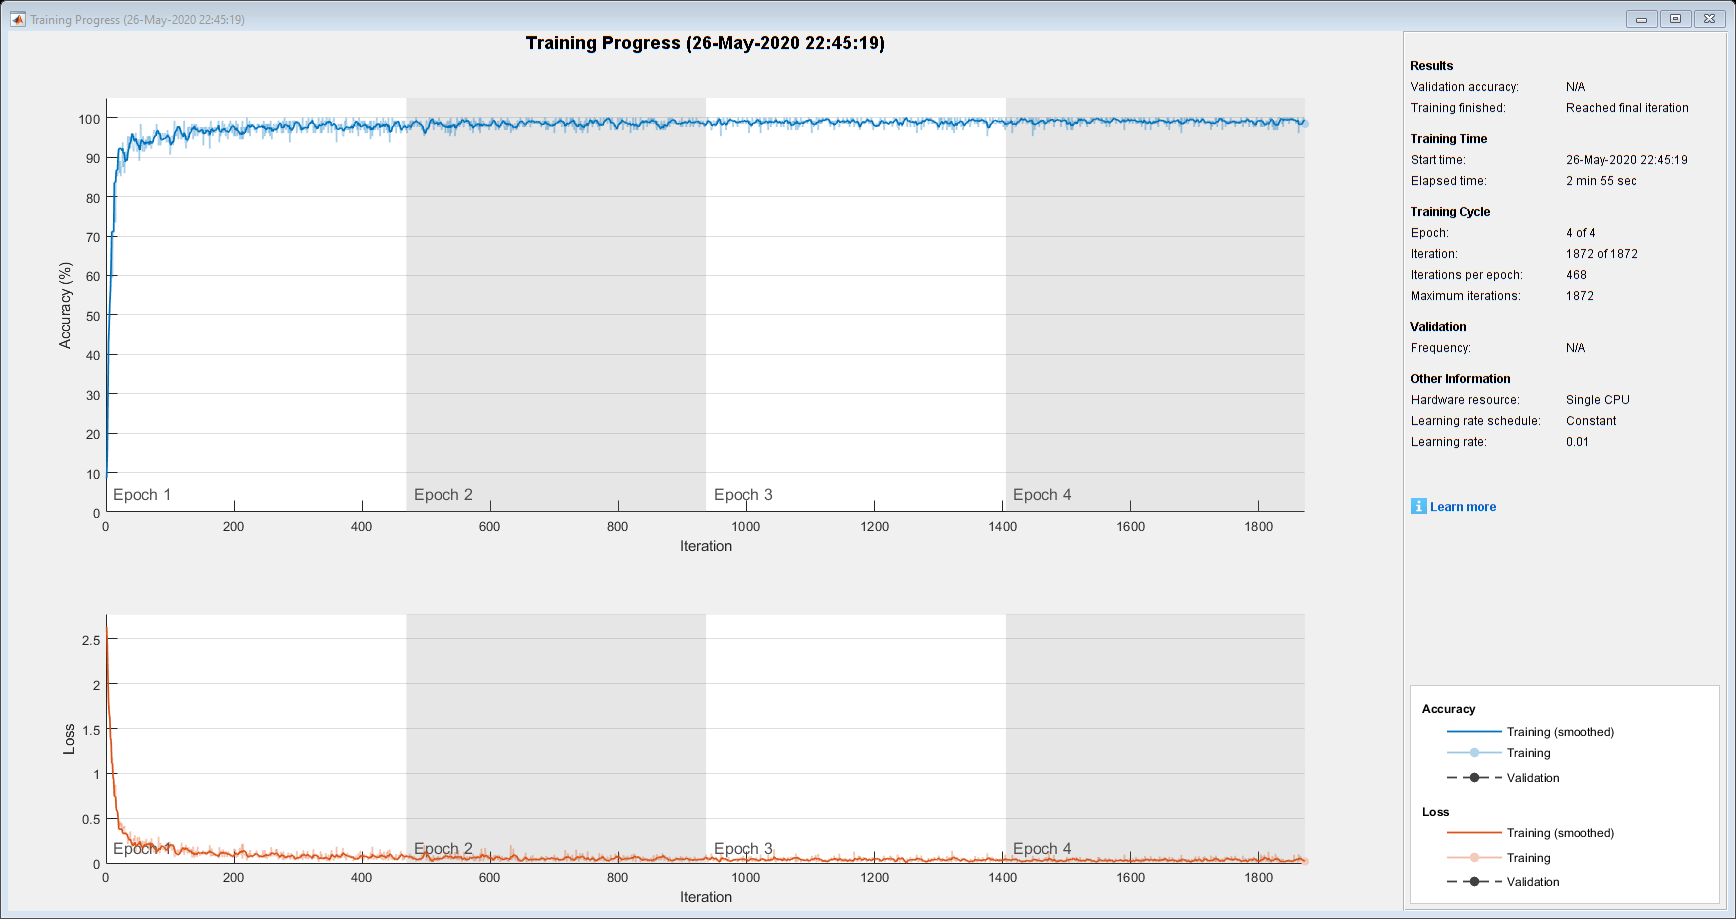

net = trainNetwork(trainimages, trainlabels,layers,options);

Classify Validation Images and Compute Accuracy

labelsPredict = classify(net,images);
accuracy = sum(labelsPredict == labels)/length(labels)

acc = 0.9932

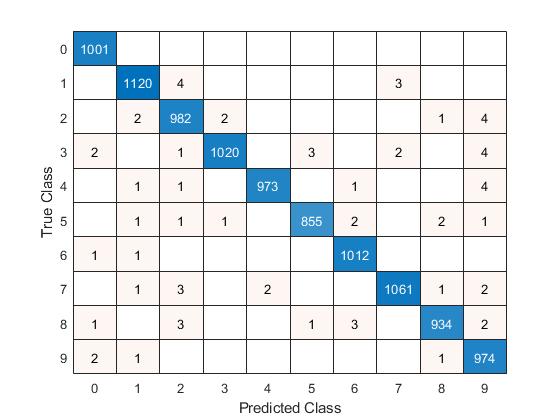

confusionchart(labels,labelsPredict)